依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Transfer PCA

[~,TransferPcaScore]=TransferLearning.UnifiedPcaModel(Paradigm="光声");

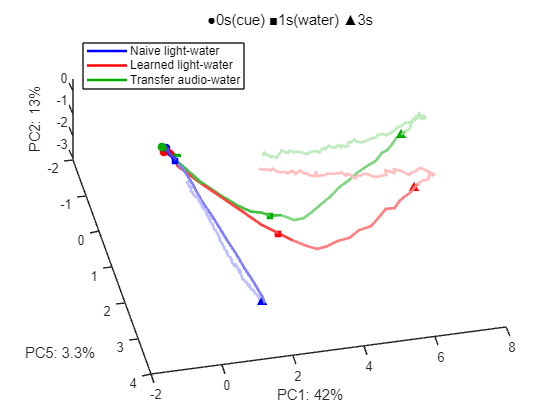

PCs=[5,1,2];
PcaScore=permute(TransferPcaScore.Score{PCs,:,["Naive_light_water","Learned","Transfer"]},[3,1,2]);
LinesPC=table;
LinesPC.Points=PcaScore;
LinesPC.Color=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Markers=table;
Markers.Index=[24;32;48];
Markers.Shape=('os^')';
figure;
Lines=UniExp.SegmentFadePlot(LinesPC,Markers,PatchArguments={'LineWidth',2});
Explained=TransferPcaScore.Explained(PCs);
UniExp.PcAxLabels(table(PCs',Explained,'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]));
legend(Lines,["Naive light-water","Learned light-water","Transfer audio-water"],Interpreter='none',Location='northwest');
title('●0s(cue) ■1s(water) ▲3s');
view(90*(1-Explained(1)*2/(Explained(1)*2+Explained(2))),90*(1-Explained(3)/sum(Explained)));
print(TransferLearning.ProjectPath('Fig1H.png'),'-dpng','-r200');